# 2.

clear; close all;

## a)

rs = 450 %km

rs = 450

ws = 8e-4 %rad/s

ws = 8.0000e-04


B = [0 0; 1 0; 0 0; 0 1];
A = [0 1 0 0; 3*ws^2 0 0 2*ws; 0 0 0 1; 0 -2*ws 0 1]

A =          0    1.0000         0         0
    0.0000         0         0    0.0016
         0         0         0    1.0000
         0   -0.0016         0    1.0000



%Vamos a mirar los autovalores de A para mirar que la desviación de la
%órbita va a cero.
[vA, lA] = eig(A)

vA =          0    1.0000    1.0000    0.0011
         0   -0.0014    0.0014    0.0011
    1.0000    0.0016    0.0016    0.7071
         0   -0.0000    0.0000    0.7071


lA =          0         0         0         0
         0   -0.0014         0         0
         0         0    0.0014         0
         0         0         0    1.0000



%The orbit is fucken unstable because hay dos autovalores no negativos.

## b)

%Tests de controlabilidad y observabilidad
%Primero, con los sensores disponibles
C1 = [1; 0; 0; 0;]; %Detector 1
C3 = [0; 0; 1; 0;]; %Detector 3
C4 = [0; 0; 0; 1;]; %Detector 4
C = [C1 C3 C4]' 

C =      1     0     0     0
     0     0     1     0
     0     0     0     1



robs = rank(obsv(A, C))

robs = 4

El rango es 4, luego el sistema es observable.

ract = rank(ctrb(A, B))

ract = 4

El rango también es 4, luego ya sabemos que el sistema también es controlable. El saboteador cylon ha fracasado.

## c)

%De nuevo en vez de LQR voy a usar control por realimentación de estados estimados. 
%Primero, para el estimador
L = place(A', C', [-5 -6 -7 -8])' %Acker solo funciona para sistemas de una entrada.

L =    14.0118         0   -1.7417
   48.1543         0  -12.5190
         0    5.0000    1.0000
   -0.0525         0    7.9882


K = place(A, B, [-1 -2 -3 -4])

K =     3.0038    4.0017    0.1583    0.0651
    0.1211    0.0504    7.9962    6.9983


## d)

x0 = [1 0.3 2 0.4]'

x0 =     1.0000
    0.3000
    2.0000
    0.4000


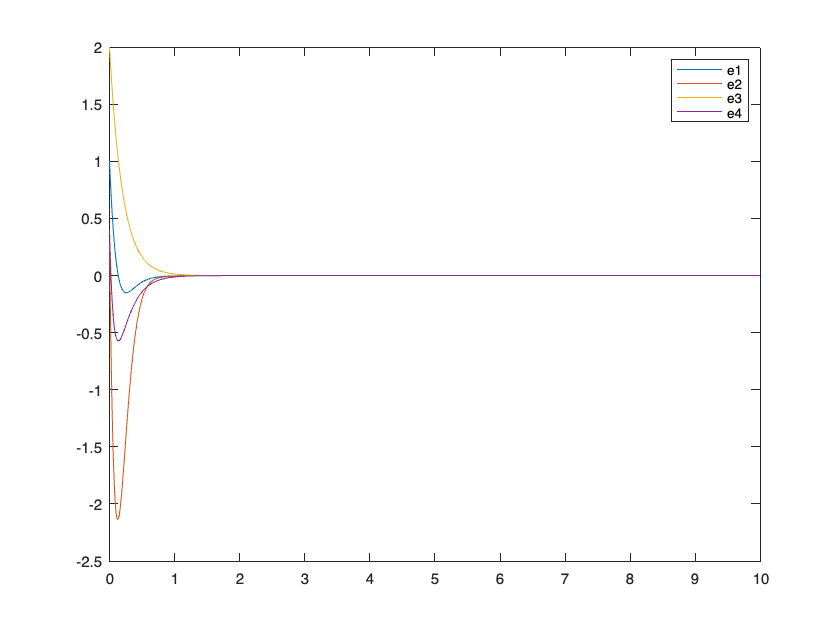

%Ecuación 4.56 para el estimador 4.40 para el control

[t, x] = ode45(@(t, x) controlador_estimador(t, x, A, B, K, L, C), [0 10], [x0; 0; 0; 0; 0]); %Los últimos 4 estados son los del estimador.
figure(1)
plot(t, x(:, 1:4) - x(:, 5:8))
legend("e1", "e2", "e3", "e4");

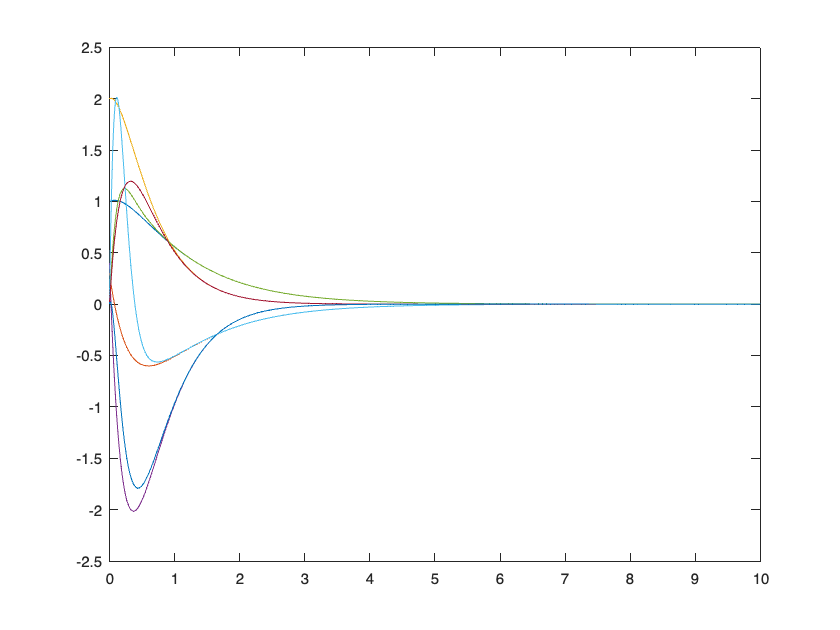


figure(2)
plot(t, x)

## e)

Vamos a estudiar la controlabilidad si se pierde uno de los dos propulsores.

Brad = [0 0; 0 0; 0 0; 0 1]; %Perdiendo el propulsor tangencial
rank(ctrb(A, Brad))

ans = 4


Btan = [0 0; 0 1; 0 0; 0 0]; %Perdiendo el propulsor tangencial
rank(ctrb(A, Btan))

ans = 3

Se puede ver que conviene proteger el radial porque si lo perdemos la matriz de controlabilidad del sistema pierde rango. También se ve que no pasa nada si se fastidia el tangencial.

## f)

Cs1 = [zeros(4,1) C3 C4]'; %Perdiendo el 1
rank(obsv(A, Cs1))

ans = 4


Cs3 = [C1 zeros(4,1) C4]'; %Perdiendo el 3
rank(obsv(A, Cs3))

ans = 3


Cs4 = [C1 C3 zeros(4,1)]'; %Perdiendo el 4
rank(obsv(A, Cs3))

ans = 3

Estudiando los rangos, se ve que hay que proteger el sensor 3 para no perder observabilidad.

# 3.

## a)

A = [-1 1 0; 1 -2 1; 0 1 -1]

A =     -1     1     0
     1    -2     1
     0     1    -1


[vA, lA] = eig(A)

vA =    -0.4082   -0.7071    0.5774
    0.8165    0.0000    0.5774
   -0.4082    0.7071    0.5774


lA =    -3.0000         0         0
         0   -1.0000         0
         0         0   -0.0000


Mirando los autovalores y autovectores, se ve que el autovector de autovalor 0 (estado de equilibrio) tiene las tres temperaturas iguales.

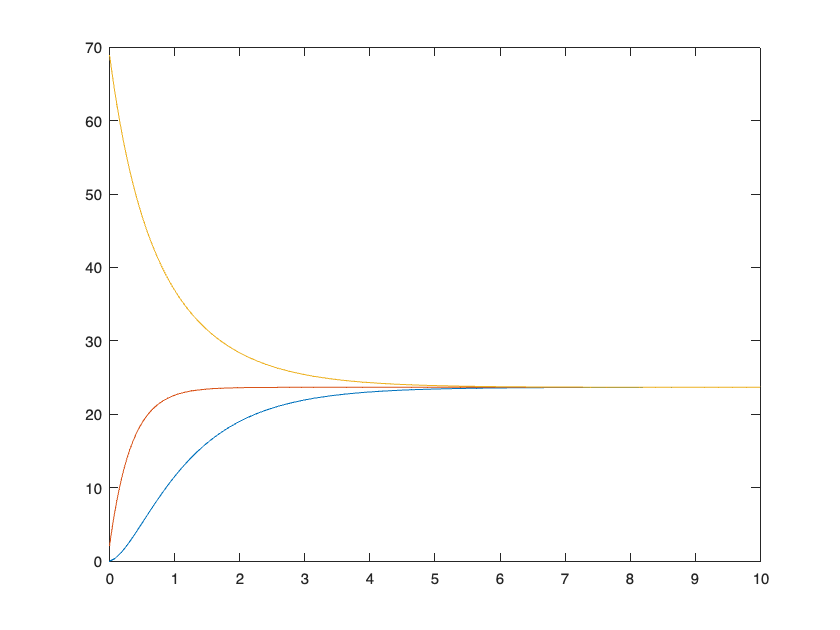

[t, x] = ode45(@(t, x) A * x, [0 10], [0 2 69]');
figure(3)
plot(t, x)

Parece que efectivamente las tres temperaturas convergen a un mismo punto.

## **b)**

%Como z1 = x1 - x2 y z2 = x2 - x3
%zdot1 = x2 - x1 - x1 + x2 +x2 - x3 = 2z1 + z2
%zdot2 = x1 + x3 -2x2 -x2 + x3
Az = [-2 1; 1 -2]

Az =     -2     1
     1    -2


[vAz, lAz] = eig(Az)

vAz =     0.7071    0.7071
   -0.7071    0.7071


lAz =     -3     0
     0    -1


Parece que todas las diferencias de temperatura van a converger a cero, luego sí es coherente a que tiendan a un punto x1 = x2 = x3.

## c)

Vamos a estudiar la controlabilidad del sistema. 

%Recuperando los autovectores de A
vA

vA =    -0.4082   -0.7071    0.5774
    0.8165    0.0000    0.5774
   -0.4082    0.7071    0.5774


Se ve que solo es necesaria una bomba, pero no puede estar colocada en la habitación del centro, ya que el segundo autovector pertenecería al kernel de B'.

%Si comprobamos con la matriz de controlabilidad. Pongamos la bomba en la
%habitación 1.
B1 = [1 0 0]'

B1 =      1
     0
     0


Con1 = [B1, A*B1, A^2*B1]

Con1 =      1    -1     2
     0     1    -3
     0     0     1


rank(Con1)

ans = 3

%El rango es 3. El sistema es controlable.
B2 = [0 1 0]'

B2 =      0
     1
     0


Con2 = [B2, A*B2, A^2*B2]

Con2 =      0     1    -3
     1    -2     6
     0     1    -3


rank(Con2)

ans = 2

%El rango es 2. El sistema no es controlable.

Se pide hacer una señal de control en lazo abierto de mínima energía para llevar las temperaturas de x0 a x1 en un tiempo t1 - t0. La señal tendrá la forma

$u\left(t\right)={B\left(t\right)}^T e^{A\left(t_1 -t\right)} \eta$,

donde


$$\eta ={\mathrm{Wr}\left(t_0 ,t_1 \right)}^{-1} x_1$$



$$\mathrm{Wr}\left(t_0 ,t_1 \right)=\int_{t_0 }^{t_1 } e^{A\left(t_1 -t\right)} \cdot \;B\cdot B^T \cdot e^{A^T \left(t_1 -t\right)} \mathrm{dt}$$


Si suponemos que vamos a usar la bomba de la habitación 1, es decir, B = (1 0 0)'

%Para un tf = 10s, x1 = [10 10 10]', x0 = [0 2 1]'
x1 = [270; 265; 280];
x0 = [273; 273; 273];
B = [1 0 0]'

B =      1
     0
     0


t1 = 12

t1 = 12

f = @(t) expm(A*(t1 - t)) * B * B' * expm(A'*(t1 - t));
Wr = integral(f, 0, t1, "ArrayValued", 1)

Wr =     1.8750    1.4306    1.2500
    1.4306    1.2778    1.1806
    1.2500    1.1806    1.1250


eta = Wr\(x1-x0)

eta = 1.0e+03 *

    0.2924
   -1.2870
    1.0319


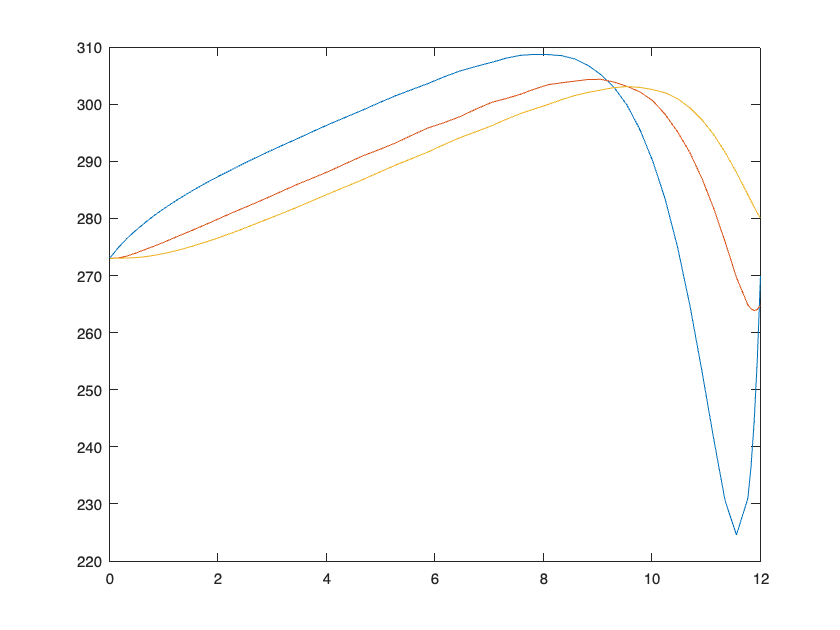


[t, x] = ode45(@(t, x) A * x + B * B' * expm(A'*(t1 - t)) * eta, [0 12], x0);
figure(4)
plot(t, x)

function zdot = controlador_estimador(t, z, A, B, K, L, C)
    zdot(1:4,1) = A * z(1:4,1) - B * K * z(1:4,1); 
    zdot(5:8,1) = A * z(5:8,1) - B * K * z(5:8,1) - L * C * (z(5:8,1) - z(1:4,1));
end 

